CS 567 (HW3)

Sparsh Agarwal

9075905142

Q1. (a) Yes the images are same, because the default window size used in medfilt2 is 3*3 which we did ourselves.

img_new = zeros(304,304);
img_new(2:end-1,2:end-1) = dat(:,:);
img_filtered = zeros(302,302);

rhovect = zeros(9,1);
for i = 2:303
    for j = 2:303
        temp = img_new(i-1:i+1,j-1:j+1);
        temp = temp(:);
        temp = sort(temp);
        img_filtered(i-1,j-1) = temp(5);
    end
end

img_filtered_func = medfilt2(dat);

% minint_2=min(min(img_new));
% img_new=img_new-minint_2;
% maxint_2=max(max(img_new));
% img_new=img_new/maxint_2*63;

% minint_1=min(min(img_filtered)); 
% img_filtered=img_filtered-minint_1; 
% maxint_1=max(max(img_filtered)); 
% img_filtered=img_filtered/maxint_1*63;
% 
% minint_func=min(min(img_filtered_func)); 
% img_filtered_func=img_filtered_func-minint_func; 
% maxint_func=max(max(img_filtered_func)); 
% img_filtered_func=img_filtered_func/maxint_func*63;

diff = img_filtered_func-img_filtered;

max(max(diff(:)))

ans = 0

min(min(diff(:)))

ans = 0

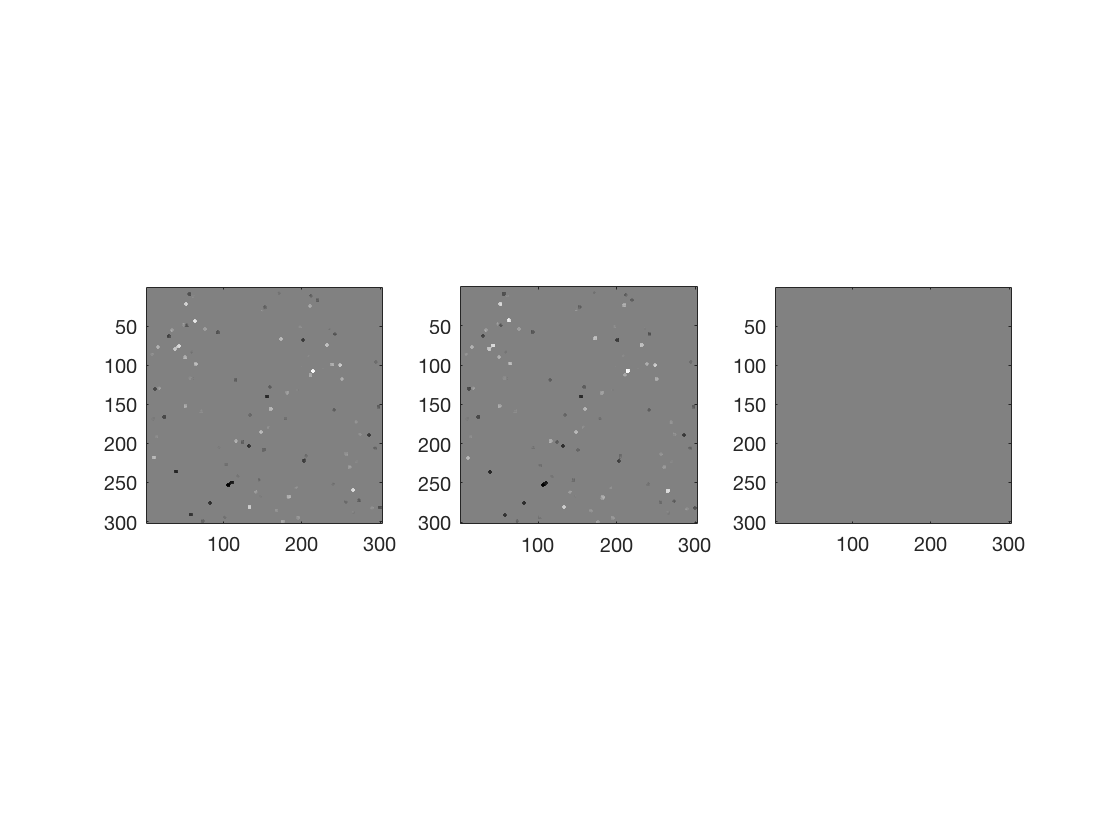


figure
subplot(1,3,1)
imagesc(img_filtered)
colormap(gray)
axis('image')
subplot(1,3,2)
imagesc(img_filtered_func)
colormap(gray)
axis('image')
subplot(1,3,3)
imagesc(diff)
colormap(gray)
axis('image')

(b) The minimum filter size to remove all salt and pepper is 11*11

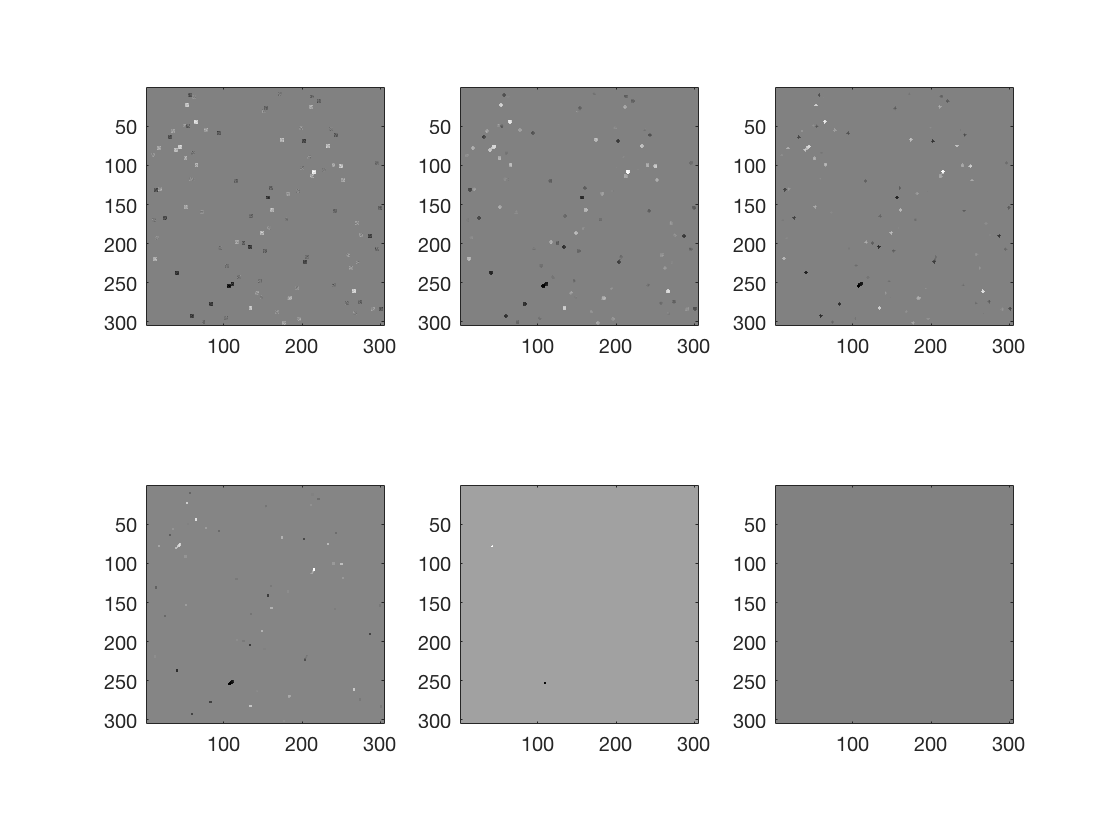

img_new = zeros(304,304);
img_new(2:end-1,2:end-1) = dat(:,:);
img_filtered = zeros(304,304,29);

for i = 1:2:11
    img_filtered(:,:,(i+1)/2)= medfilt2(img_new, [i i]);
%     minint=min(min(img_filtered(:,:,i)));
%     img_filtered(:,:,i)=img_filtered(:,:,i)-minint;
%     maxint=max(max(img_filtered(:,:,i)));
%     img_filtered(:,:,i)=img_filtered(:,:,i)/maxint*63;
end

% minint_1=min(min(img_new));
% img_new=img_new-minint_1;
% maxint_1=max(max(img_new));
% img_new=img_new/maxint_1*63;

figure
for i = 1:6
    subplot(2,3,i)
    imagesc(img_filtered(:,:,i))
    colormap(gray)
    axis('image')
end

% subplot(5,6,30)
% imagesc(img_new)
% colormap(gray)
% axis('image')

(c) To remove isolated salt and peppers, the median array should have values in midlle as the background. For this the sorted array need to have number of background pixel values greater than the number of salt pixel values. Therefore if the salt pixel is 5*5 i.e 25 pixels, the filter should have min of 51 pixels where midlle pixel is a background pixel. Thus the square filter should be a 9*9( not 8*8 = 64, since an odd side matrix is require) matrix to remove all isolated pixels using median filtering. 

This solution is not the same as previous part because there are many salt and pepper which are very close to each other and to remove them we would need larger median filter, thus 11*11 is required.

Q2.  Thresholding at 14% of maximum if found to be best. For the entire pocess, I first applied the median filter to remove most of the salt and pepper without loosing much of edge properties. Then I used mean filter to further smooth out any salt and pepper bits left and smoothen the edges. After that I applied the center_x and center_y approach to find the gradients along each axis. From those gradients, I found the edges using squareroot of sum of squares of 2 gradients. After edge detection, there is a need to binarize the image to apply hough transform. I tested with multiple thresholds and 10 found out to be best, to threshold the edge detected image (found from gradients). After getting binarized image, to get the optimal set of line, there is a need to threshold the accumulator matrix found from the binarized  image. 14% of maximum found out to be the most optimal to find the optimal nmber of edges using our implementation of hough transform. We used theta and distance from origin as two parameter to define each line. At the end we plotted the lines found fused with the original image.

% img_new = zeros(462,382);
% img_new(2:end-1,2:end-1) = dat_hough(:,:);
% img_filtered = zeros(462,382,49);

% for i = 1:49
% %     m = ones(i,i) / (i*i);
% %     img_filtered(:,:,i) = imfilter(img_new,m);
%     img_filtered(:,:,i)= medfilt2(img_new, [i i]);
% %     minint=min(min(img_filtered(:,:,i)));
% %     img_filtered(:,:,i)=img_new-minint;
% %     maxint=max(max(img_filtered(:,:,i)));
% %     img_filtered(:,:,i)=img_filtered(:,:,i)/maxint*63;
% end
% 
% figure
% for i = 1:49
%     subplot(7,7,i)
%     imagesc(img_filtered(:,:,i))
%     colormap(gray)
%     axis('image')
% end
img_new = ones(470,390).*63;
img_new(6:end-5,6:end-5) = dat_hough(:,:);
img_filtered_final = zeros(470,390);

img_filtered_final(:,:)= medfilt2(img_new, [11 11]);

m = ones(3,3) / (3*3);
img_filtered_final(:,:) = imfilter(img_filtered_final,m);

convmat_x = zeros(3,3);
convmat_x(3,2) = -0.5;
convmat_x(1,2) = 0.5;
conv_out_x = conv2(img_filtered_final, convmat_x, 'same');

convmat_y = zeros(3,3);
convmat_y(2,3) = -0.5;
convmat_y(2,1) = 0.5;
conv_out_y = conv2(img_filtered_final, convmat_y, 'same');

grad = sqrt(conv_out_x.^2+conv_out_y.^2);
max(max(grad(:)))

ans = 31.6938

min(min(grad(:)))

ans = 0

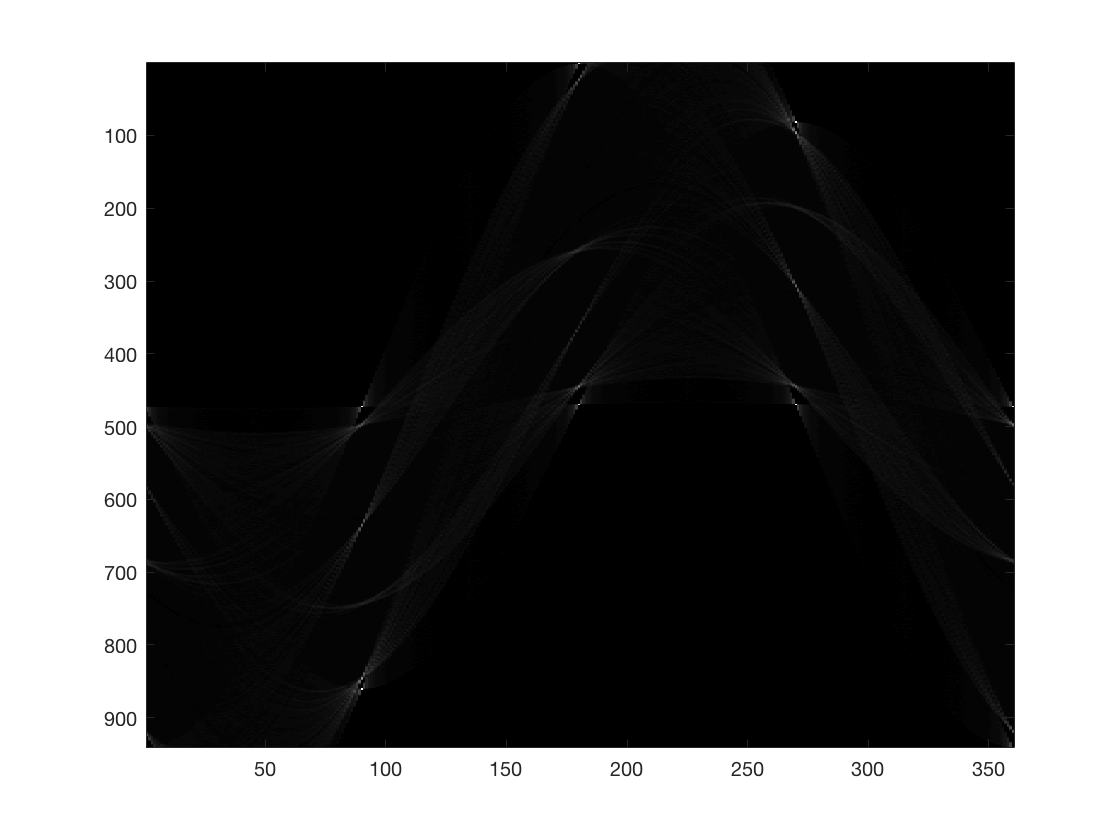

gradb = grad>10;
% figure
% imagesc(grad)


% figure
% subplot(1,3,1)
% imagesc(img_new)
% axis('image')
% subplot(1,3,2)
% imagesc(img_filtered_final)
% axis('image')
% subplot(1,3,3)
% imagesc(grad) 
% axis('image')
% title('Edge detection using gradient')
% colormap('gray')
addpath ~/OneDrive/'Spring 2018'/'CS 567'/Medical-Imaging/'HW 3'/

open('hough_trans')

% Run the hough_transform function

[himg, theta, r] = hough_trans(gradb);


% plot 
figure
imagesc(himg)
colormap(gray)

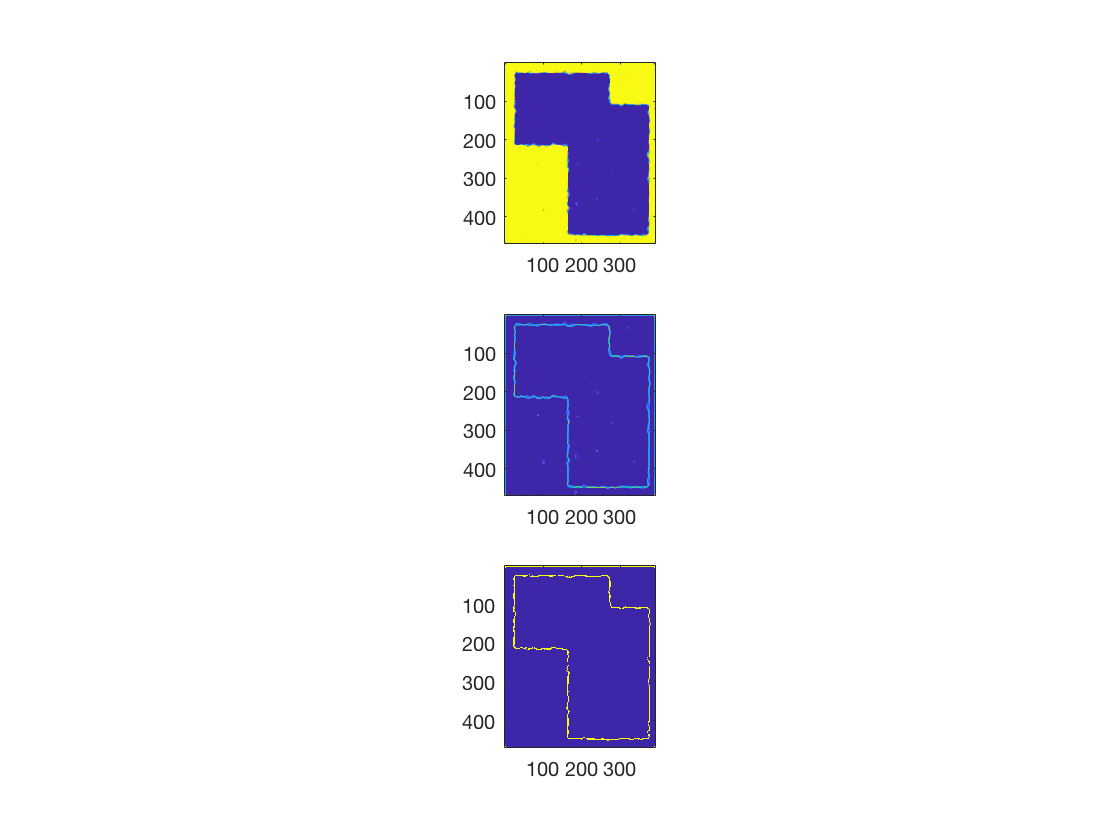



% for k=1:.2:2
    maxint=max(max(himg));
%     [i, j] = find(himg > 0.1*k*maxint);
    [i, j] = find(himg > 0.14*maxint);
    theta_rad = theta*pi/180;
    
    slopes = -1*cos(theta_rad(j))./sin(theta_rad(j));
    intercepts = r(i)./sin(theta_rad(j));
    
    %ymax = size(img,2);
    
    
    img_lines = zeros(size(gradb));
    n_lines = length(slopes);
    for i = 1:n_lines
      xval = [1:0.1:size(gradb,1)]'; %Over sample x for now (will round later)
      yval = intercepts(i) + xval*slopes(i);
      xval = round(xval);
      yval = round(yval);
      keep = yval< size(gradb,2) & yval>0;
      xval_keep = xval(keep);
      yval_keep = yval(keep);
      for index = 1:length(xval_keep)
         img_lines(xval_keep(index), yval_keep(index)) = 1;
      end
    end
    
%     figure
%     subplot(1, 2, 1)
%     imagesc(gradb)
%     subplot(1, 2, 2)
%     imagesc(img_lines)
%     colormap(gray)
    
%      fused_img = imfuse(img_filtered_final, img_lines);
%      figure
%      imagesc(fused_img)
% end
figure
subplot(3,1,1)
imagesc(img_filtered_final)
axis('image')
subplot(3,1,2)
imagesc(grad)
axis('image')
subplot(3,1,3)
imagesc(gradb)
axis('image')

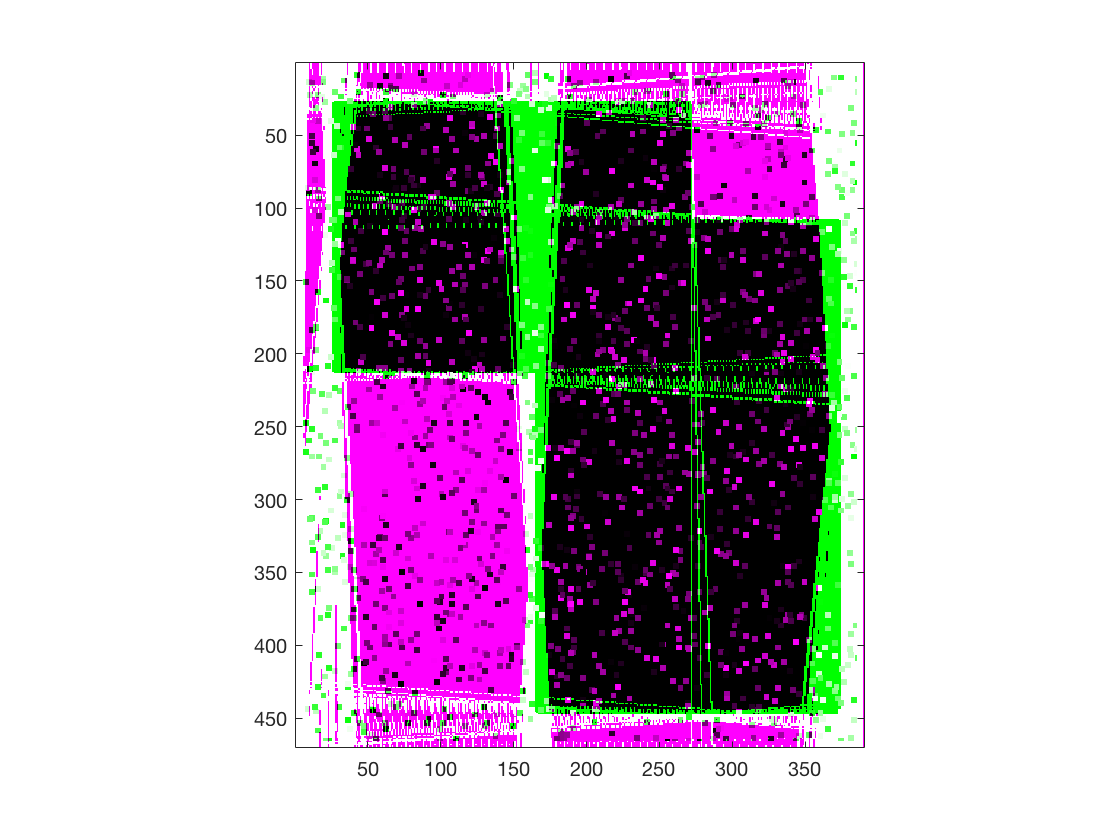

fused_img = imfuse(img_lines, img_new);
figure
imagesc(fused_img)
axis('image')

Q3. (1)

num_pos_x = 540;
num_pos_y = 720;

% we will store our values in himg...since r can be negative, we'll create
% an r-vector to keep track of what locations in himg correspond to the
% values of r and a theta vector that does the same

i_rng = size(img_circle, 1);
j_rng = size(img_circle, 2);

rad = 48:2:52;
theta = 0:359;
ring=zeros(num_pos_x, num_pos_y, length(rad));
for i=1:i_rng
    for j=1:j_rng
        if img_circle(i,j) > 0
            k = 0;
            for r=rad
                k = k + 1;
                for ang=theta
                    x = i-(r*cos(ang*3.14/180));
                    y = j-(r*sin(ang*3.14/180));
                    if x>=0.5 && y>=0.5 && x<=540 && y<=720
                        ring(round(x), round(y), k)=ring(round(x), round(y), k)+1;
                    end
                end
            end
        end
    end
end


(2) 48 is found to be best radius

for i = 1:length(rad)
    max(max(ring(:,:,i)))
end

ans = 212

ans = 139

ans = 81

(3)

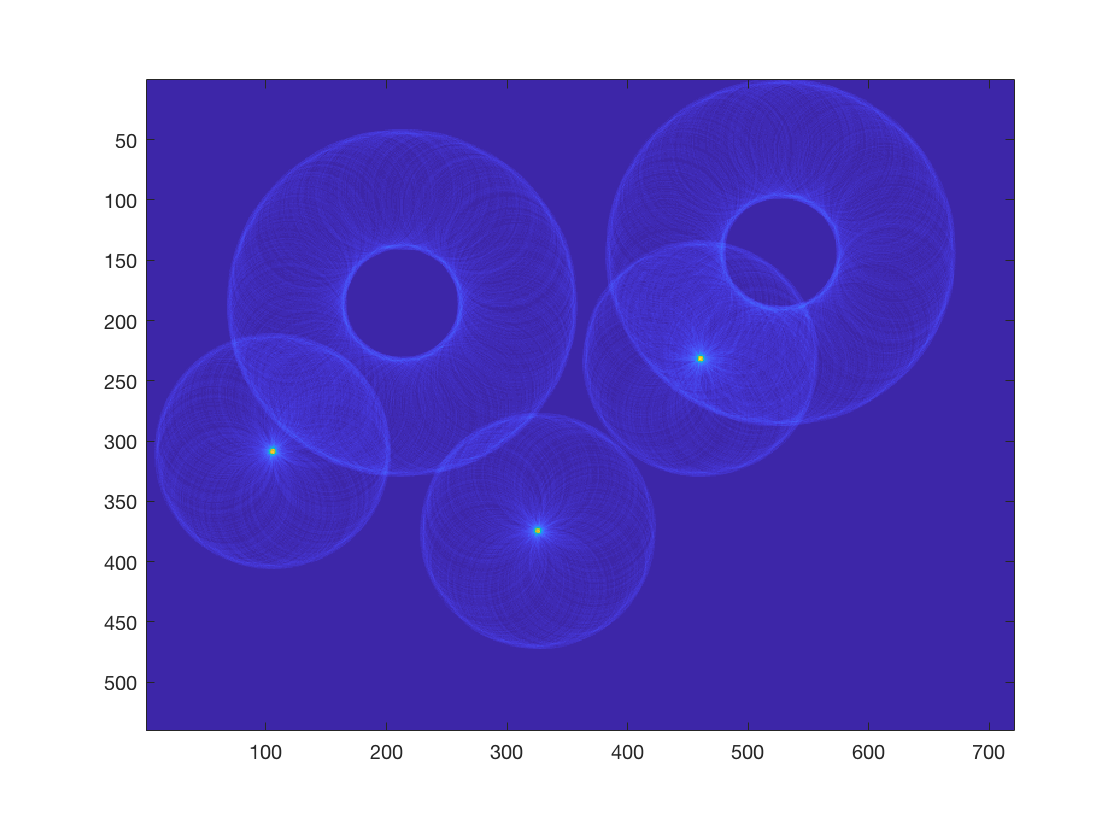

% figure
% for k=4:.5:9.5
    maxint=max(max(ring(:,:,1)));
%     [i_pts,j_pts] = find( 0.1*k+0.5*maxint > ring(:,:,3) > 0.1*k*maxint);
%     [i_pts,j_pts] = find( ring(:,:,3) > 0.1*k*maxint);
    maximum = max(max(ring(:,:,1)));
    minimum = min(min(ring(:,:,1)));
    ring_pts = ring(:,:,1)>0.70*maximum;
    figure
    imagesc(ring(:,:,1))
    axis('image')

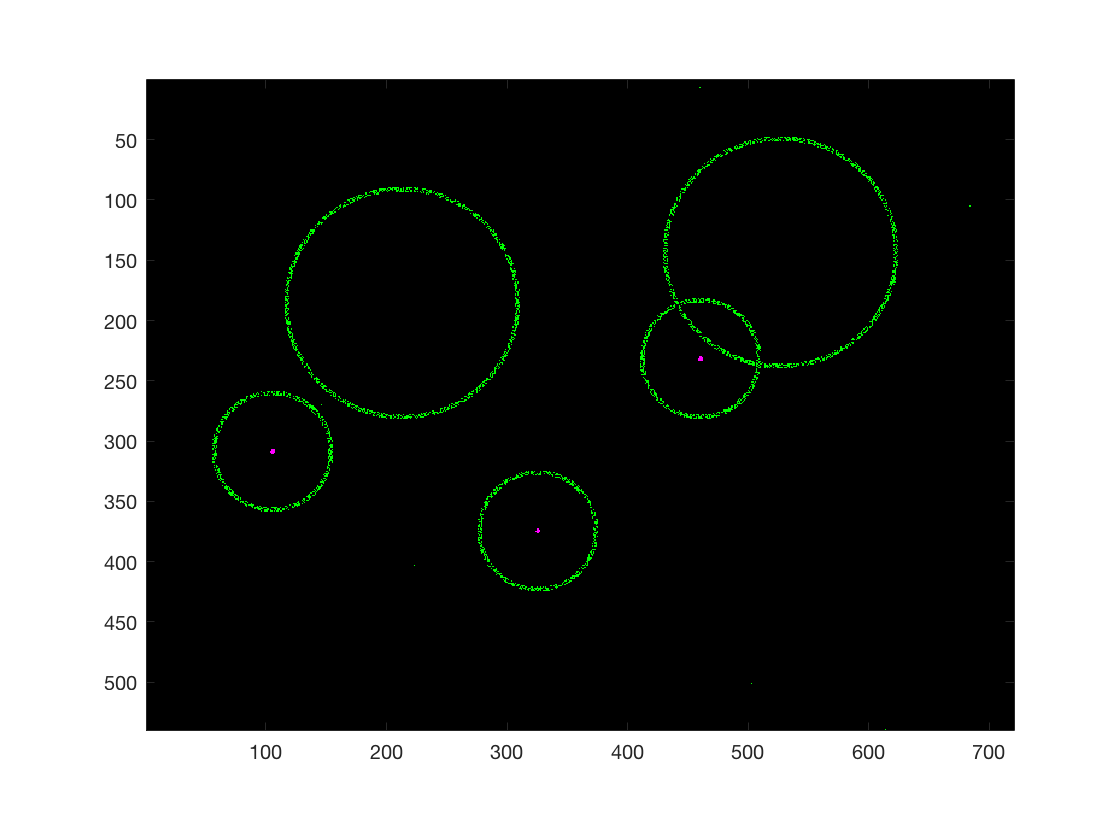

    
    fused_img = imfuse(img_circle, ring_pts);
    figure
%     subplot(3,4,k*2-7)
    imagesc(fused_img)
%     colormap(gray)
    axis('image')

% end
